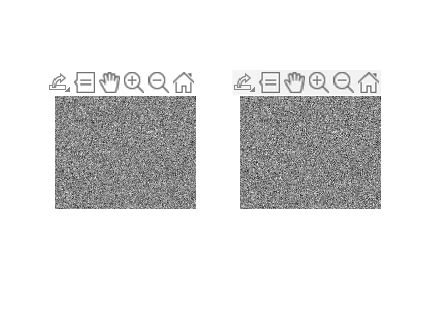

clear
clc

load('snow.mat');
[ACstream, DCstream, h, w] = JpegEncoder(snow);
Image_Decoded = JpegDecoder(DCstream,ACstream,h,w);
subplot(1,2,1);
imshow(snow);
title('Original');
subplot(1,2,2);
imshow(Image_Decoded);
title('Compressed');

计算PSNR

MSE = sum((Image_Decoded-snow).^2,'all')/h/w;
PSNR = 10 * log10(255^2/MSE);

PSNR = 29.5614

由于原图高频分量很多，量化时主要对高频分量进行了压缩，所以图像失真较大。

计算压缩比

compressrate = 8*h*w/(length(ACstream)+length(DCstream));

compressrate = 3.6450

由于高频分量较多，长游程项更多，所以huffman码长较长，且对AC部分编码时EOB出现较晚，所以AC码流显著变长，压缩比较低